## Figure 3 and Supplementary Figure S5

We only present the results of the variant 1 for the chemostat fit, but the files for running the other prior-posterior graphs are given.

### Variant 1 - Chemostat

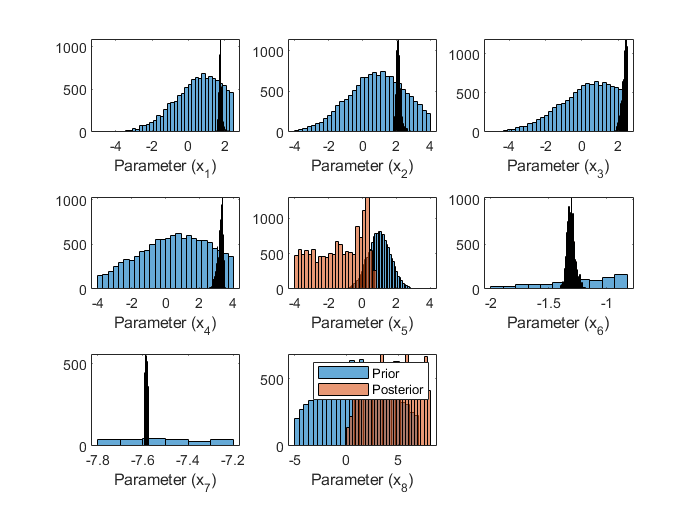

clear all clc
% Calling Parameters for Prior Distribution %
A=load('C:\Doctorado\Programa\Nuevo_PECCAD\NEW ATRAZINE\GENE BASED MODELS\AT_engi_soil\example_parameter_fits\variant_1_chemostat.mat');
% Calling Calibrated Parameters %
load('C:\Doctorado\Programa\Nuevo_PECCAD\NEW ATRAZINE\GENE BASED MODELS\AT_engi_soil\example_parameter_fits\accepted_parameters_chemostat_V1.mat')
% Prior Distribution %
y  =    A.p.*randn(length(Pars),1) + 1;
Y1 =	[log10(300) 4 log10(300) 4 4 log10(0.15) -7.2 7];
Y2 =	[-5 -4 -5 -4 -4 log10(0.01) -7.8 -5];

%Plotting%
for i = 1:8
subplot(3,3,i)
A4 = histogram(y(:,i),'BinLimits',[Y2(i),Y1(i)]);
hold on
A5 = histogram(Pars(:,i));
xlabel('Parameter (x_{' + string(i) + '})')
end
legend([A4 A5],{'Prior','Posterior'})
hold off